This section loads the fuzzy inference system from file

clc; % clear command window
clear; % clear workspace

fis = readfis('Mamdani_Fuzzy_Logic'); % load fuzzy logic variable from Fuzzy Logic Designer

This section performs necessary initialization and prompts the user to input the robot's starting location, followed by the destination.

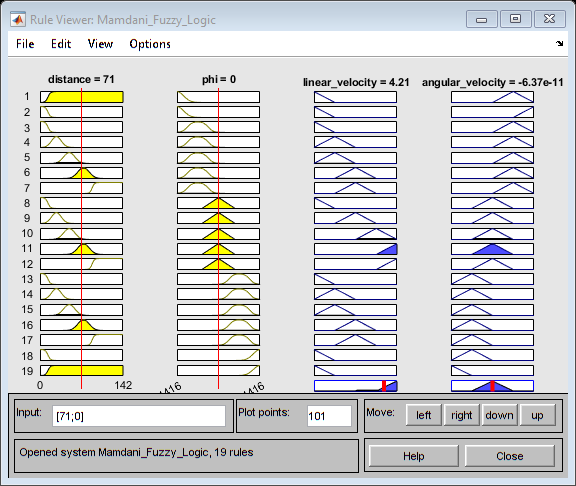

% initialization & user input
dlgTitle = 'Input Robot''s starting & destination coordinates'; % dialogue title
prompt = {'X (range = [0,100]): ', 'Y (range = [0,100]): '};    % dialogue prompt
dims = [1 35];                  % dialogue dimensions
definput = {'0','0'};           % default inputs
startLocation = inputdlg(prompt, dlgTitle, dims, definput);     % yields a 2x1 cell
startLocation = str2double(startLocation);                      % convert input to numeric type double
startLocation = startLocation';                                 % convert from 2x1 to 1x2
dlgTitle = 'Input Robot''s destination coordinates';            % dialogue title
definput = {'50', '50'}; % default inputs
destinationLocation = inputdlg(prompt, dlgTitle, dims, definput); % yields a 2x1 cell
destinationLocation = str2double(destinationLocation);      % convert input to numeric type
destinationLocation = destinationLocation';                 % convert from 2x1 to 1x2
currentAngle = 0;                 % starting angle = 0
currentLocation = startLocation;  % robot's currentLocation is the startLocation bc it has not moved yet
distance = calculateDistance(currentLocation, destinationLocation); % calculate initial distance between robot and destination
atDestination = false;            % robot does not start at the destination
ruleview(fis);                    % open Fuzzy Logic Ruleviewer

linear_velocity = 2.8964

angular_velocity = -0.1404

linear_velocity = 2.7336

angular_velocity = -0.1725

linear_velocity = 2.5425

angular_velocity = -0.2099

linear_velocity = 2.3233

angular_velocity = -0.2500

linear_velocity = 2.3186

angular_velocity = -0.2501

linear_velocity = 2.3135

angular_velocity = -0.2503

linear_velocity = 2.2942

angular_velocity = -0.2519

linear_velocity = 2.0400

angular_velocity = -0.2612

linear_velocity = 1.4997

angular_velocity = -0.3133

linear_velocity = 0.7978

angular_velocity = -0.3886

linear_velocity = 0.6559

angular_velocity = -0.4008

linear_velocity = 1.4566

angular_velocity = -0.3185

linear_velocity = 1.9990

angular_velocity = -0.2635

linear_velocity = 1.9953

angular_velocity = -0.2637

linear_velocity = 1.9916

angular_velocity = -0.2639

linear_velocity = 1.9879

angular_velocity = -0.2642

linear_velocity = 1.9846

angular_velocity = -0.2644

linear_velocity = 1.9836

angular_velocity = -0.2644

linear_velocity = 1.9826

angular_velocity = -0.2645

linear_velocity = 1.9816

angular_velocity = -0.2645

linear_velocity = 1.9806

angular_velocity = -0.2646

linear_velocity = 1.9796

angular_velocity = -0.2646

linear_velocity = 1.9786

angular_velocity = -0.2647

linear_velocity = 1.9776

angular_velocity = -0.2647

linear_velocity = 1.9766

angular_velocity = -0.2648

linear_velocity = 1.9756

angular_velocity = -0.2648

linear_velocity = 1.9746

angular_velocity = -0.2649

linear_velocity = 1.9736

angular_velocity = -0.2649

linear_velocity = 1.9726

angular_velocity = -0.2650

linear_velocity = 1.9716

angular_velocity = -0.2650

linear_velocity = 1.9706

angular_velocity = -0.2651

linear_velocity = 1.9696

angular_velocity = -0.2652

linear_velocity = 1.9686

angular_velocity = -0.2652

linear_velocity = 1.9675

angular_velocity = -0.2653

linear_velocity = 1.9665

angular_velocity = -0.2653

linear_velocity = 1.9655

angular_velocity = -0.2654

linear_velocity = 1.9645

angular_velocity = -0.2654

while (~atDestination) % while robot is not at the destination
    % calculate next generation of linear & angular velocities
    nextGen = calculateNextGen(fis, currentLocation, currentAngle, destinationLocation); 
    linear_velocity = nextGen(1);
    angular_velocity = nextGen(2);

    % calculate the next theta and (x,y) coordinates from the velocities
    currentAngle = getNextTheta(angular_velocity, currentAngle);                        % calculate next theta from angular velocity
    currentLocation = getNextLocation(linear_velocity, currentLocation, currentAngle);  % calculate next (x,y) location from linear velocity
    [currentLocation, currentAngle] = withinBounds(currentLocation, currentAngle);      % ensure robot is within [0,100]x[0,100] plane
    distance = calculateDistance(currentLocation, destinationLocation);                 % Calculate the distance between the robot and its destination
    atDestination = isAtDestination(currentLocation, destinationLocation);              % check if robot is at destination
    visualize(fis, currentLocation, currentAngle, destinationLocation)                  % create plot
    
    % output linear_velocity, angular_velocity
    linear_velocity
    angular_velocity
end


clf % clear plot
scatter(currentLocation(:,1),currentLocation(:,2), '.b'); % plot currentLocation as a point
scatter(destinationLocation(:,1),destinationLocation(:,2), 'xk','DisplayName', 'Destination'); % plot destinationLocation as a point
legend({'Destination'});

The following section contains functions which are necessary for computing input values, output values, as well as creating the plot as a visual aid

% calculateNextGen
%
% parameters: fis
%             currentLocation
%             currentAngle
%             destinationLocation
% return: next generation of linear_velocity & angular_velocity

function nextGen = calculateNextGen(fis, currentLocation, currentAngle, destinationLocation)
    phi = calculatePhi(currentAngle, currentLocation, destinationLocation);
    phi = phi(1);
    distance = calculateDistance(currentLocation, destinationLocation);
    nextGen = evalfis(fis, [distance, phi]);
end


% visualize
%
% draws the plot of the robot on the plane AND waits 0.100 s before
% returning
%
% parameters: currentLocation
%             currentAngle
%             destinationLocation
%
function visualize(fis, currentLocation, currentAngle, destinationLocation)   
    hold on
    axis manual  
    axis([0,100,0,100])
    f1 = scatter(currentLocation(:,1),currentLocation(:,2), '.b', 'DisplayName', 'Robot'); 
    scatter(destinationLocation(:,1),destinationLocation(:,2), 'xk', 'DisplayName', 'Destination');
    xlabel = 'X';
    ylabel = 'Y';
    legend({'Destination'});
    %currentLocationVector = [currentLocation(1)+cos(currentAngle), currentLocation(2)+sin(currentAngle)];
    %f3 = line(currentLocation, currentLocationVector);
    pause(0.100); % pause execution for 100 ms
    delete(f1);
    %delete(f3);
    %hold off
end

% calculatePhi
%
% This function calculates the angle between the robot's current
% angle and the destination
%
% parameters: currentAngle, currentLocation, destinationLocation
% return: phi, the angle between the robot and the destination
%
function phi = calculatePhi(currentAngle, currentLocation, destinationLocation)
    currentLocationVec = destinationLocation - currentLocation;
    destinationVec = [cos(currentAngle), sin(currentAngle)];
    temp = dot(destinationVec, currentLocationVec)/(norm(destinationVec)*norm(currentLocationVec));
    if (temp >= 1)
        temp = 1;
    end
    if (temp <= -1)
        temp = -1;
    end
    phi = acos(temp);
    phi = phi(1);
end

% calculateDistance
%
% calculates the distance between two given points
%
% parameters: current_coords
%             destination
% return: distance between two points
%
function distance = calculateDistance(current_coords, destination)
    temp = current_coords-destination;
    temp = temp.^2;
    distance = sqrt(temp(1) + temp(2));
end


% getNextLocation
%
% This function calculates the robot's next (x,y) location
% based on its current location, current theta, and linear_velocity
%
% parameters: linear_velocity
%             currentLocation
%             theta
%
function nextLocation = getNextLocation(linear_velocity, currentLocation, theta)
    delta_t = 0.100; % change in time = 100 ms
    delta_x = linear_velocity*delta_t;
    delta_x_x = delta_x * cos(theta);
    delta_x_y = delta_x * sin(theta);
    nextLocation = [currentLocation(1)+delta_x_x currentLocation(2)+delta_x_y];
end

% getNextTheta
%
% This function calculates the robot's next value of theta
% based on its current theta and angular_velocity.
%
% parameters: angular_velocity
%             theta               
% return: nextTheta
%
function nextTheta = getNextTheta(angular_velocity, theta)
    nextTheta = theta + angular_velocity; 
end

% isAtDestination
%
% This function returns true if the robot is at the destination.
% 
% parameters: currentLocation
%             destination
% return: boolean, true if robot is at destination +/- 0.05, false otherwise
%
function atDestination = isAtDestination(currentLocation, destination)
    episilon = 0.05;
    dist_xy = destination - currentLocation;
    atDestination = false;
    if (abs(dist_xy(1)) <= episilon)
        if (abs(dist_xy(2)) <= episilon)
            atDestination = true;
        end
    end
end


% withinBounds
%
% adjusts the robot's coordinates such that they are still within the 
% [0,100]x[0,100] range and adjusts the robot's angle such that it is
% still within the [-pi, pi] range.
%
% parameters: currentLocation
%             currentAngle
% return: currentLocation
%         currentAngle  
%
function [currentLocation, currentAngle] = withinBounds(currentLocation, currentAngle)
    if (currentLocation(1) > 100)
        currentLocation(1) = 100;
    end
    if (currentLocation(2) > 100)
        currentLocation(2) = 100;
    end
    if (currentLocation(1) < 0)
        currentLocation(1) = 0;
    end
    if (currentLocation(2) < 0)
        currentLocation(2) = 0;
    end
    if (currentAngle < -1*pi)
        currentAngle = -1*pi;
    end
    if (currentAngle > pi)
        currentAngle = pi;
    end
    if (currentAngle == 2*pi || currentAngle == -2*pi)
        currentAngle = 0;
    end
end